%% ECM307-G01T02L03D - Atividade T3
%% Atividade T3 - Análise de Vogais
%% Luis Guilherme de Souza Munhoz RA: 20.01937-8 Lab: 3
%% Instruções

%%%% primeiro descomente a sessão de leitura
%%%% em seguida comente a sessão de análise
%%%% agora rode o código
%%%% depois comente a sessão de leitura e descomente a sessão de análise e
%%%% rode o código novamente
%% Boas Práticas

clc;                                       % limpa a tela
clear all;                                 % limpar as variáveis
close all;                                 % fecha as figuras abertas
%% Leitura das vogais e armazenamento em arquivo Vogais.mat

% prealocando
a = cell(1,5);
a{1,5} = [];

% prealocando
e = cell(1,5);
e{1,5} = [];

% prealocando
i = cell(1,5);
i{1,5} = [];

% prealocando
o = cell(1,5);
o{1,5} = [];

% prealocando
u = cell(1,5);
u{1,5} = [];

for ii = 1:5
%%%% Leitura da vogal a
    File = "a" + ii + ".wav";
    
    [Y,FS] = audioread(File);
    
    a{:,ii} = Y;
    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% Leitura da vogal e
    File = "e" + ii + ".wav";

    [Y,FS] = audioread(File);
    

    e{:,ii} = Y;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% Leitura da vogal i
    File = "i" + ii + ".wav";

    [Y,FS] = audioread(File);

    i{:,ii} = Y;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% Leitura da vogal o
    File = "o" + ii + ".wav";

    [Y,FS] = audioread(File);

    o{:,ii} = Y;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% Leitura da vogal u
    File = "u" + ii + ".wav";
    
    [Y,FS] = audioread(File);

    u{:,ii} = Y;

end
save('Vogais.mat', 'a', 'e', 'i', 'o', 'u');
%% Carregando o arquivo das vogais e as analisando

k = 0;
jj = 0;
% preallocation
a = cell(1,5);

% preallocation
e = cell(1,5);

% preallocation
i = cell(1,5);

% preallocation
o = cell(1,5);

% preallocation
u = cell(1,5);

load('Vogais.mat')
FS = 44100;
Ts = 1/FS;
% for ii = 1:5
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% analise da vogal a    
%     %%%%% reduzindo o tamanho de a
%     N       = length(a{:,ii});               
%     Ts      = 1/FS;                     
%     ws      = 2*pi*FS;                
%     duracao = N*Ts;                    
%     tempo   = linspace(0,duracao,N);   
%     fmax    = FS/2;
%     k = k + 1;
% 
%     %%%% espectro de amplitude
% 
% 
%     figure(1)
%     frequencia = linspace(0,FS,N);
%     subplot(5,5,k);
%     plot(frequencia,fftshift(abs(fft(a{:,ii}))));
%     title("a" + ii);
% 
%     
%     %%%% plotando a série temporal
%     
% 
%     figure(2)
%     N       = length(a{:,ii});
%     duracao = N*Ts; 
%     tempo   = linspace(0,duracao,N);
%     subplot(5,5,k);
%     plot(tempo, a{:,ii});
%     title("a" + ii);
%     
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% analise da vogal e    
%     %%%%% reduzindo o tamanho de e
%     
%     N       = length(e{:,ii});               
%     Ts      = 1/FS;                     
%     ws      = 2*pi*FS;                
%     duracao = N*Ts;                    
%     tempo   = linspace(0,duracao,N);   
%     fmax    = FS/2;
%     k = k + 1;
% 
%     %%%% espectro de amplitude
% 
% 
%     figure(1)
%     frequencia = linspace(0,FS,N);
%     subplot(5,5,k);
%     plot(frequencia,fftshift(abs(fft(e{:,ii}))));
%     title("e" + ii);
% 
%     
%     %%%% plotando a série temporal
%     
% 
%     figure(2)
%     N       = length(e{:,ii});
%     duracao = N*Ts; 
%     tempo   = linspace(0,duracao,N);
%     subplot(5,5,k);
%     plot(tempo, e{:,ii});
%     title("e" + ii);
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% analise da vogal i    
%     %%%%% reduzindo o tamanho de i
%     N       = length(i{:,ii});               
%     Ts      = 1/FS;                     
%     ws      = 2*pi*FS;                
%     duracao = N*Ts;                    
%     tempo   = linspace(0,duracao,N);   
%     fmax    = FS/2;
%     k = k + 1;
% 
%     %%%% espectro de amplitude
% 
% 
%     figure(1)
%     frequencia = linspace(0,FS,N);
%     subplot(5,5,k);
%     plot(frequencia,fftshift(abs(fft(i{:,ii}))));
%     title("i" + ii);
% 
%     
%     %%%% plotando a série temporal
%     
% 
%     figure(2)
%     N       = length(i{:,ii});
%     duracao = N*Ts; 
%     tempo   = linspace(0,duracao,N);
%     subplot(5,5,k);
%     plot(tempo, i{:,ii});
%     title("i" + ii);
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% analise da vogal o    
%     %%%%% reduzindo o tamanho de o
%     N       = length(o{:,ii});               
%     Ts      = 1/FS;                     
%     ws      = 2*pi*FS;                
%     duracao = N*Ts;                    
%     tempo   = linspace(0,duracao,N);   
%     fmax    = FS/2;
%     k = k + 1;
% 
%     %%%% espectro de amplitude
% 
% 
%     figure(1)
%     frequencia = linspace(0,FS,N);
%     subplot(5,5,k);
%     plot(frequencia,fftshift(abs(fft(o{:,ii}))));
%     title("o" + ii);
% 
%     
%     %%%% plotando a série temporal
%     
% 
%     figure(2)
%     N       = length(o{:,ii});
%     duracao = N*Ts; 
%     tempo   = linspace(0,duracao,N);
%     subplot(5,5,k);
%     plot(tempo, o{:,ii});
%     title("o" + ii);
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% analise da vogal u   
%     %%%%% reduzindo o tamanho de u
%     N       = length(u{:,ii});               
%     Ts      = 1/FS;                     
%     ws      = 2*pi*FS;                
%     duracao = N*Ts;                    
%     tempo   = linspace(0,duracao,N);   
%     fmax    = FS/2;
%     k = k + 1;
% 
%    %%%% espectro de amplitude
% 
% 
%     figure(1)
%     frequencia = linspace(-FS/2,FS/2,N);
%     subplot(5,5,k);
%     plot(frequencia,fftshift(abs(fft(u{:,ii}))));
%     title("u" + ii);
% 
%     
%     %%%% plotando a série temporal
%     
% 
%     figure(2)
%     N       = length(u{:,ii});
%     duracao = N*Ts; 
%     tempo   = linspace(0,duracao,N);
%     subplot(5,5,k);
%     plot(tempo, u{:,ii});
%     title("u" + ii);
% end
%% análise da primeira vogal a

figure(3);
t0 = 0.908329;
N       = length(a{:,1});
duracao = N*Ts; 
Vp = a{:,1}(39690:44999);
tempo   = linspace(0,duracao,N)-t0;
tempoa1 = linspace(tempo(39690), tempo(44999), length(Vp))

tempoa1 =    -0.0083   -0.0083   -0.0083   -0.0083   -0.0083   -0.0082   -0.0082   -0.0082   -0.0082   -0.0081   -0.0081   -0.0081   -0.0081   -0.0080   -0.0080   -0.0080   -0.0080   -0.0080   -0.0079   -0.0079   -0.0079   -0.0079   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0077   -0.0077   -0.0077   -0.0077   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0075   -0.0075   -0.0075   -0.0075   -0.0074   -0.0074   -0.0074   -0.0074   -0.0073   -0.0073   -0.0073   -0.0073   -0.0073   -0.0072


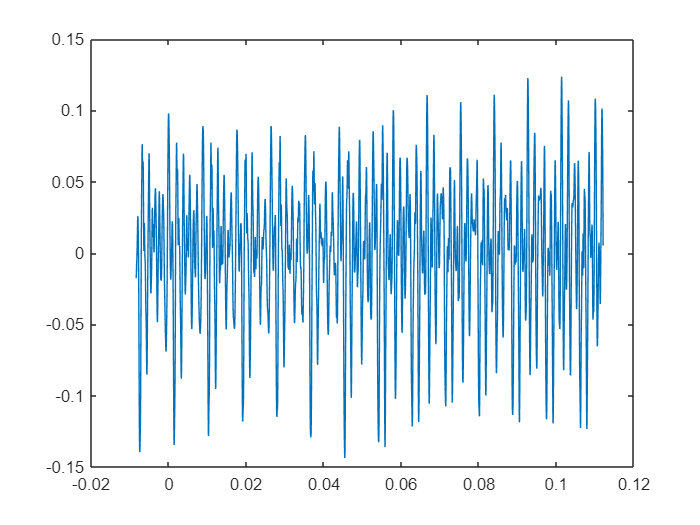


plot(tempoa1,Vp)


frequencia = linspace(0,FS/2,N/2);
frequencia = frequencia(0.4*N:0.42*N);

Y0 = abs(fft(a{:,1}));
Y0 = Y0(0.9*N:0.92*N);

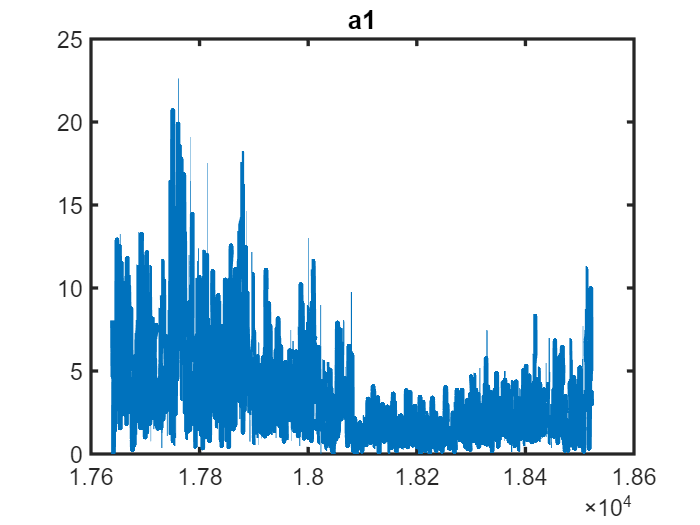

plot(frequencia,fftshift((Y0)));
title("a"+ 1);
%% Modifica parâmetros do gráfico

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);

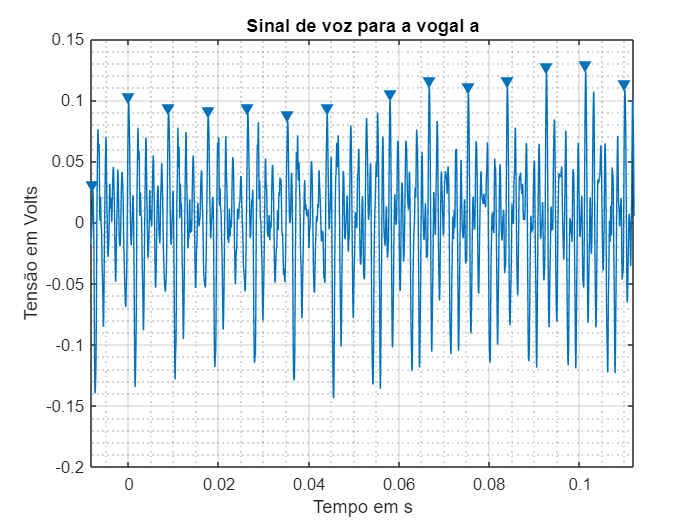


%%% Analisando os parâmteros graficamente

ti = 0.00174627;  % começo do primeiro período inteiro
tf = 0.109774;   % fim do último período inteiro

T = (tf-ti)/14; % valor médio dentre os 14 períodos
f = inv(T);     % frequência associada a vibração gerada

findpeaks(Vp,tempoa1,'MinPeakDistance',T);

[vt,tp]=findpeaks(Vp,tempoa1,'MinPeakDistance',T);

Tm =mean(diff(tp));

title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid minor

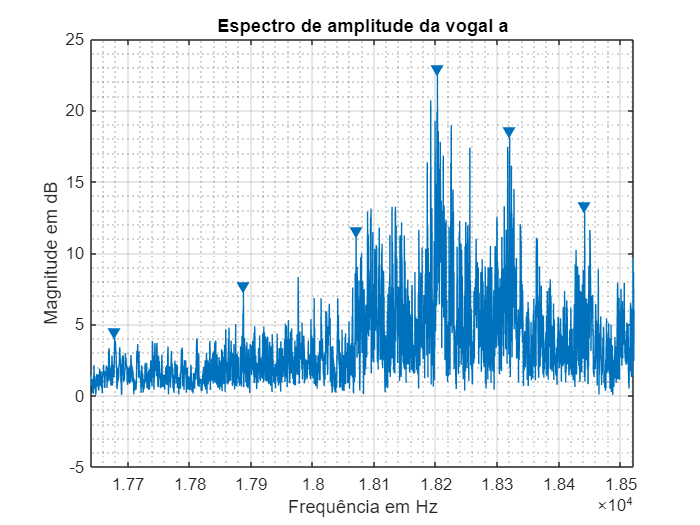


findpeaks(Y0,frequencia,'MinPeakDistance',0.9*f);

title('Espectro de amplitude da vogal a');
xlabel('Frequência em Hz');
ylabel('Magnitude em dB'); 
grid minor 

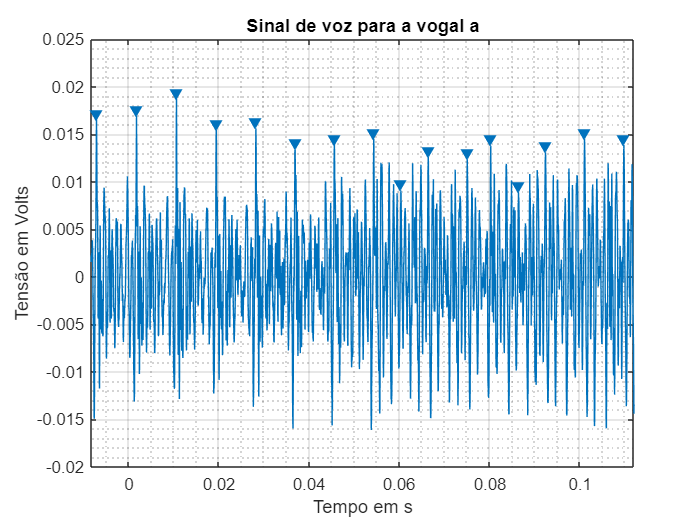


[Md,fp]=findpeaks(Y0,frequencia,'MinPeakDistance',0.9*f);
%% Analisando o sinal de Voz

t = tempoa1;
findpeaks(diff(Vp),t(1:end-1),'MinPeakDistance',0.001,'MinPeakDistance',0.005);
[vt,ip] = findpeaks(diff(Vp),t(1:end-1),'MinPeakDistance',0.001,'MinPeakDistance',0.005);

title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid minor

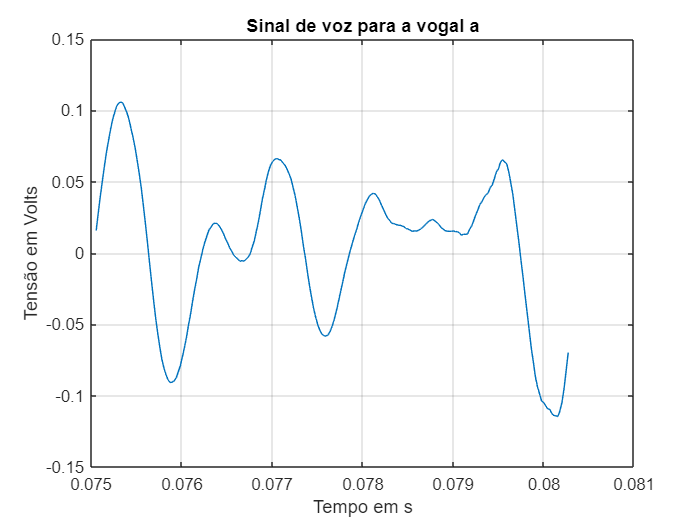


inicio =  find(t==ip(11));
fim    =  find(t==ip(12));

plot(t(inicio:fim),Vp(inicio:fim));
title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid 

clear("Y");
X = t(inicio:fim) - t(inicio);
Y = Vp(inicio:fim);

[vexp,texp] = findpeaks(Y,X,'MinPeakDistance',0.001);

f = fit(texp(1:3)',vexp(1:3)','exp1')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.1188  (0.02348, 0.2142)
       b =      -335.1  (-919.2, 248.9)

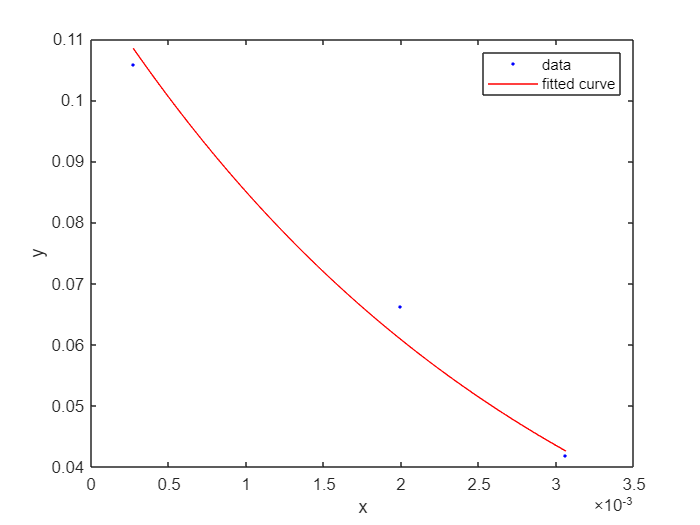

plot(f,texp(1:3)',vexp(1:3))

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Otimizando


x=[0 0.1188 -335.1 730]';

% Plot the original and experimental data.

Y_new =  x(1) + x(2).*exp(x(3).*X).*sin(2*pi*x(4).*X)

Y_new =          0    0.0122    0.0242    0.0356    0.0466    0.0568    0.0663    0.0750    0.0827    0.0893    0.0950    0.0995    0.1028    0.1051    0.1061    0.1060    0.1047    0.1024    0.0989    0.0945    0.0891    0.0828    0.0757    0.0680    0.0595    0.0506    0.0413    0.0317    0.0218    0.0119    0.0020   -0.0078   -0.0173   -0.0265   -0.0353   -0.0436   -0.0512   -0.0582   -0.0645   -0.0700   -0.0746   -0.0784   -0.0813   -0.0832   -0.0843   -0.0844   -0.0835   -0.0818   -0.0793   -0.0759


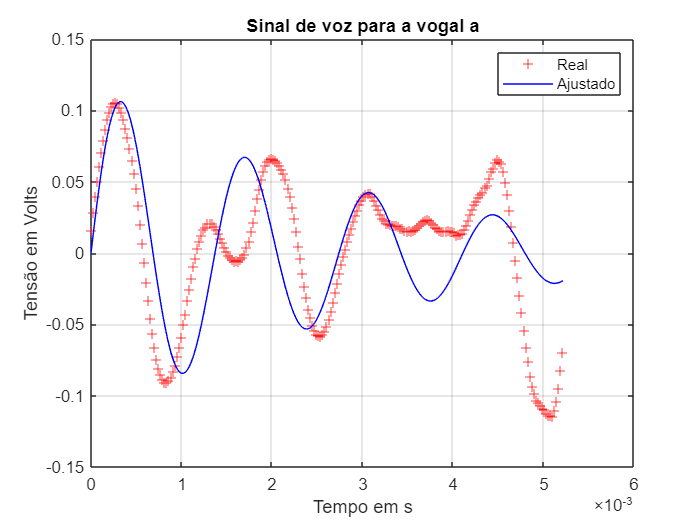


plot(X,Y,'+r',X,Y_new,'b')
title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid 
legend('Real','Ajustado')

%% Analisando as respectivas funções de transferência

% Transformando a função temporal em uma função de laplace

x=[0 0.2056 -2422 730]';
Y_new =  x(1) + x(2).*exp(x(3).*X).*sin(2*pi*x(4).*X)

Y_new =          0    0.0202    0.0380    0.0535    0.0667    0.0776    0.0864    0.0931    0.0980    0.1010    0.1024    0.1023    0.1009    0.0983    0.0947    0.0902    0.0850    0.0793    0.0731    0.0665    0.0598    0.0531    0.0463    0.0396    0.0331    0.0268    0.0209    0.0153    0.0100    0.0052    0.0008   -0.0031   -0.0066   -0.0096   -0.0122   -0.0144   -0.0161   -0.0175   -0.0185   -0.0191   -0.0195   -0.0195   -0.0193   -0.0188   -0.0182   -0.0174   -0.0164   -0.0153   -0.0142   -0.0129


clear('tf')                 % apaga a variável que impede o cálculod a função de transferência
                            % no futuro melhor mudar o nome da variável
k  = x(2)*2*pi*x(4);
p1 = x(3) + j*2*pi*x(4);
p2 = x(3) - j*2*pi*x(4);
z  = [];

Gvoz = zpk(z,[p1 p2],k)

Gvoz =
 
          943.03
  -----------------------
  (s^2 + 4844s + 2.69e07)
 
Continuous-time zero/pole/gain model.



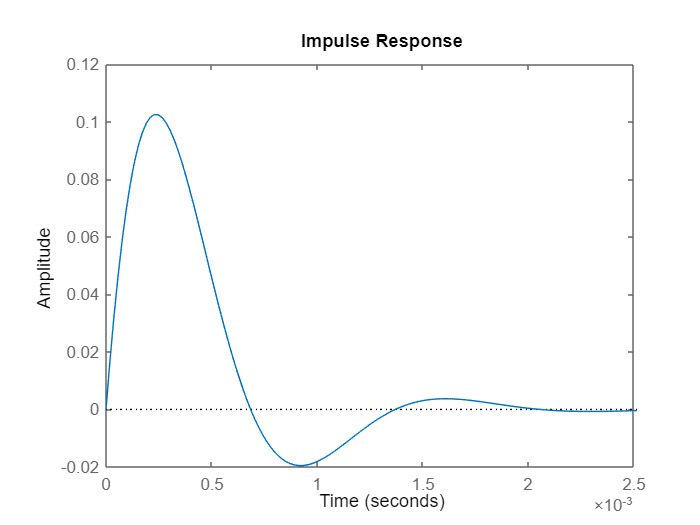

figure()
impulse(Gvoz)

Tn = 1/x(4);
Ts = Tn/20;
fs = 1/Ts;


[Zd,Pd,Kd] = bilinear(z,[p1 p2]',k,fs)

Zd =     -1
    -1


Pd =    0.8088 - 0.2624i
   0.8088 + 0.2624i


Kd = 9.2364e-07

[Nd,Dd] = zp2tf(Zd,Pd,Kd)

Nd = 	1.0e+-5 *

    0.0924    0.1847    0.0924


Dd =     1.0000   -1.6175    0.7229


Gvozd = tf(Nd,Dd,Ts)

Gvozd =
 
  9.236e-07 z^2 + 1.847e-06 z + 9.236e-07
  ---------------------------------------
          z^2 - 1.618 z + 0.7229
 
Sample time: 6.8493e-05 seconds
Discrete-time transfer function.



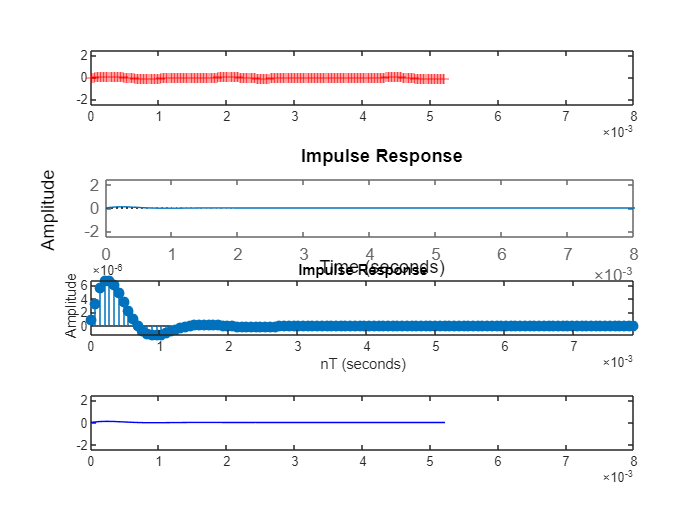

subplot(4,1,2); 
impulse(Gvoz);
axis([0 8e-3 -2.5 2.5])
subplot(4,1,3); 
impz(cell2mat(Gvozd.numerator),cell2mat(Gvozd.denominator),(8e-3/Ts),fs)
subplot(4,1,1); 
plot(X,Y,'+r')
axis([0 8e-3 -2.5 2.5])
subplot(4,1,4); 
plot(X,Y_new,'b')
axis([0 8e-3 -2.5 2.5])

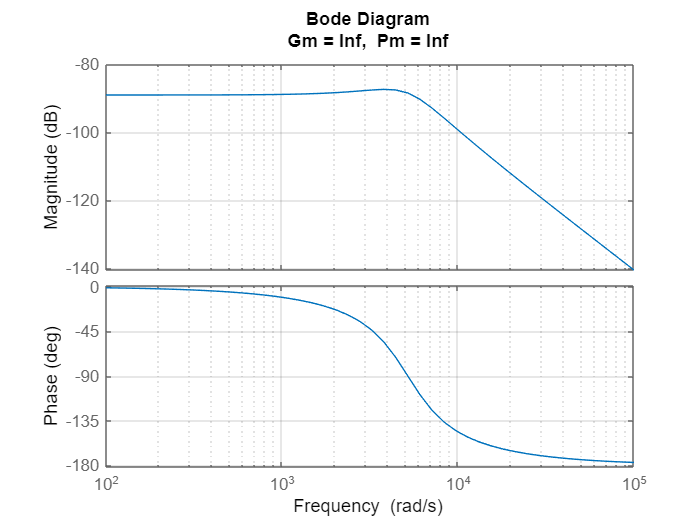

figure()
margin(Gvoz);
grid;

4551/(2*pi)

ans = 724.3141

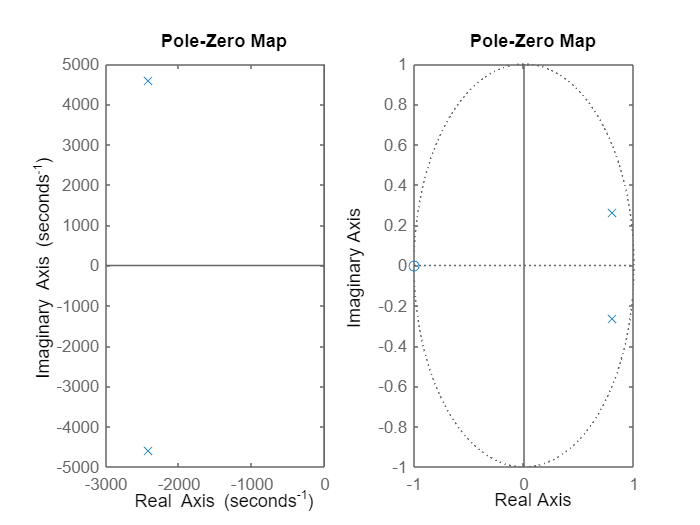



figure()

subplot(1,2,1)
pzmap(Gvoz);


subplot(1,2,2)
pzmap(Gvozd);

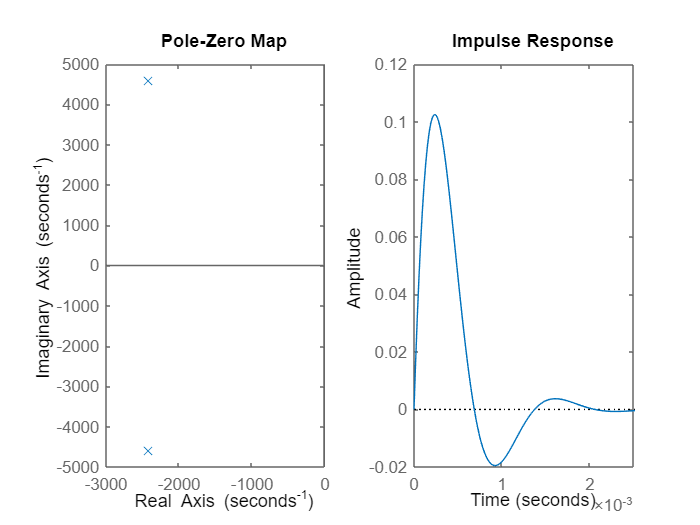



[serie,tempo,X] = impulse(Gvoz);
impulse(Gvoz)


serie            = serie';
vogal_artificial = [serie serie serie serie serie serie serie serie serie serie serie serie serie serie serie serie serie serie serie serie];
vogal_artificial = [vogal_artificial vogal_artificial vogal_artificial vogal_artificial vogal_artificial vogal_artificial vogal_artificial vogal_artificial vogal_artificial vogal_artificial vogal_artificial vogal_artificial];
sound(vogal_artificial)